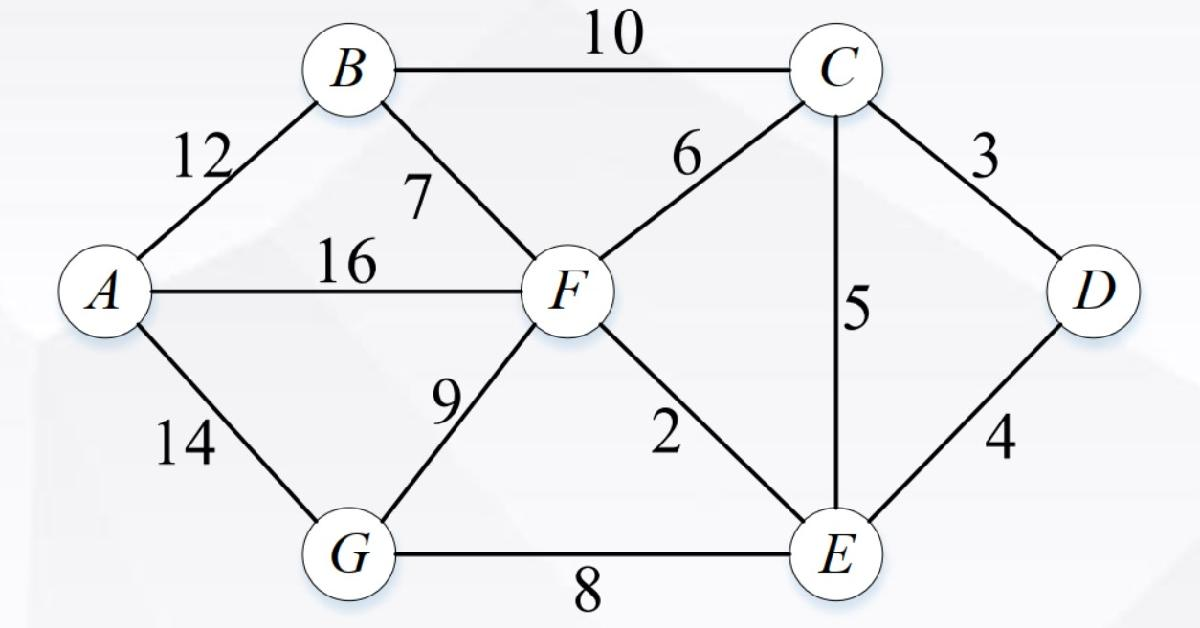

地图

字母节点-数字节点对应关系：A-1, B-2, C-3, D-4, E-5, F-6, G-7

clc
clear
close all

%% 图定义
nodes_dist = cell(0);
nodes_dist(1, :) = {1, [2, 6, 7], [12, 16, 14]};
nodes_dist(2, :) = {2, [1, 3, 6], [12, 10,  7]};
nodes_dist(3, :) = {3, [2, 4, 5, 6], [10, 3, 5, 6]};
nodes_dist(4, :) = {4, [3, 5], [3, 4]};
nodes_dist(5, :) = {5, [3, 4, 6, 7], [5,4, 2, 8]};
nodes_dist(6, :) = {6, [1, 2, 3, 5, 7], [16, 7, 6, 2, 9]};
nodes_dist(7,:)  = {7, [1, 5, 6], [14, 8, 9]};
% 节点个数
num_nodes = 7;
% 定义起点
v = 4;

%% 初始化
% S和U保存节点，第一列为节点编号，第二列为源点到对应节点的最短距离
U(:, 1) = [1:1:num_nodes]';
U(:, 2) = inf*ones(num_nodes, 1);
for i = 1 : length(nodes_dist{v, 2})    % 找到与源点相邻的点
    U(nodes_dist{v,2}(i), 2) = nodes_dist{v, 3}(i);
end

% 将源点放进S
U(v, :) = [];
S = [v, 0];

% 每个节点的前驱节点，用于最后生成路径
nodes_parent(:, 1) = (1:1:num_nodes)';
nodes_parent(:, 2) = -ones(num_nodes,1);
% 与源点相邻的节点的前驱节点设为源点(源点直接到相邻点的距离肯定最短)
for i = 1 : length(nodes_dist{v, 2})
    nodes_parent(nodes_dist{v,2}(i), 2) = v;
end

%% 寻找路径
while ~isempty(U)
    % 如果仅仅只是想找到 起点到终点 的最短距离以及路径，那么在将终点从U集移动到S集后算法即可结束。
    % 寻找U中距离最小的节点值及其索引，将其从U中放入S
    [dis_min, idx] = min(U(:, 2)); 
    node_min = U(idx, 1);
    S = [S; node_min, dis_min];
    U(idx, :) = [];

    % 依次遍历最小距离节点的邻节点，判断是否在U集合中更新邻节点的距离值
    for i = 1 : length(nodes_dist{node_min, 2})
        % 需要判断的邻节点
        node_temp = nodes_dist{node_min, 2}(i);
        % 找出U集合中节点node_temp的索引值
        idx_temp = find(node_temp == U(:,1));
        
        if ~isempty(idx_temp)
            if U(idx_temp, 2) > dis_min + nodes_dist{node_min, 3}(i)
                U(idx_temp, 2) = dis_min + nodes_dist{node_min, 3}(i);

                % 更新该点的前驱节点
                nodes_parent(node_temp, 2) = node_min;
            end
        end
    end
end

%% 打印路径
for i = 1 : num_nodes
    % 距离
    fprintf("起点 %d 到节点 %d 的距离为：%d \n", v, S(i, 1), S(i, 2));
    % 路径
    find_parent(nodes_parent, S(i, 1), S(i, 1));
    fprintf("\n")
end

起点 4 到节点 4 的距离为：0 


4.

起点 4 到节点 3 的距离为：3 


4 -> 3.

起点 4 到节点 5 的距离为：4 


4 -> 5.

起点 4 到节点 6 的距离为：6 


4 -> 5 -> 6.

起点 4 到节点 7 的距离为：12 


4 -> 5 -> 7.

起点 4 到节点 2 的距离为：13 


4 -> 3 -> 2.

起点 4 到节点 1 的距离为：22 


4 -> 5 -> 6 -> 1.

function parent = find_parent(nodes_parent, node, des)
    % 递归函数，find_parent()用于寻找前驱，直到找到源点
    idx = find(nodes_parent(:, 1) == node);
    if nodes_parent(idx, 2) == -1  % 递归结束条件：找到源点r
        parent = nodes_parent(idx, 1);
    else
        parent = find_parent(nodes_parent, nodes_parent(idx, 2), des);
    end

    if node == des
        fprintf("%d.", node);
    else
        fprintf("%d -> ", node);
    end
end